clc;
clear all;
% Define Stewart Platform Geometry
baseRadius = 75; % Radius of the base
platformRadius = 75; % Radius of the moving platform
upperLegLength = 119.0; % Length of the upper legs (platform to servo joint)
lowerLegLength = 21.1; % Length of the lower legs (servo joint to base)
servoRange = deg2rad([-90, 90]); % Range of servo angles in radians
R = eye(3); % not considering roation for now


maxLegLength = upperLegLength + lowerLegLength;
minLegLength = upperLegLength - lowerLegLength;
% max horizontal distance between endeffector and servo linkage point
maxHorizontal = 20;


beta = deg2rad([240, 240, 120, 120, 0, 0]);

% Define attachment points on the base (assumed to be at 60 degrees apart)
% theta = linspace(0, 2*pi, 7);
d = 99.10;
theta = deg2rad([13.32, 46.68, 133.32, 166.68, 253.32, 286.68]);
% theta = deg2rad([9.33, 50.67, 129.33, 170.97, 249.33, 290.67]);
% vector of where servo rotation happens
% Check to see how off the z axis is 
basePoints =  [d *cos(theta); d *sin(theta); repmat(40, 1, 6)]

basePoints =    96.4341   67.9898  -67.9898  -96.4341  -28.4443   28.4443
   22.8316   72.0986   72.0986   22.8316  -94.9301  -94.9301
   40.0000   40.0000   40.0000   40.0000   40.0000   40.0000



% Define attachment points on the moving platform
b = 75.66;
phi = deg2rad([22.41, 37.59, 142.41, 157.59, 262.41, 277.59]);
% vector of where the end of limb goes with respect to platform
platformPoints = b * [cos(phi); sin(phi); zeros(1, 6)]

platformPoints =    69.9461   59.9527  -59.9527  -69.9461   -9.9934    9.9934
   28.8440   46.1531   46.1531   28.8440  -74.9971  -74.9971
         0         0         0         0         0         0


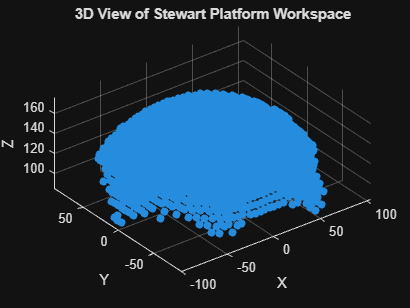


% Workspace grid resolution
xRange = -200:5:200;
yRange = -200:5:200;
zRange = 0:5:200; % Only non-negative z values
[X, Y, Z] = meshgrid(xRange, yRange, zRange);

% Initialize workspace matrix
workspace = zeros(size(X));

% Loop through all grid points
for ix = 1:length(xRange)
    for iy = 1:length(yRange)
        for iz = 1:length(zRange)
            % Current position of the moving platform
            p = [xRange(ix); yRange(iy); zRange(iz)];
            
            % Check if this position is reachable
            reachable = true;
            for i = 1:6
                % Calculate the vector from base point to platform point
                % p = transformation vector from base to platform
                % R = rotation matrix for orientation of platform
                % legVec = p + R*b_i - a_i
                legVec = p + eye(3)*platformPoints(:,i) - basePoints(:,i);
                q = p + eye(3)*platformPoints(:,i);
                % Calculate the horizontal distance from the base point to
                % the platform point (x,y) 
                horizontalDist = norm(legVec(1:2));
                
                % Calculate the vertical distance from the base point to the platform point
                verticalDist = legVec(3);

                % Calculate the distance from the base point to the platform point
                legLength = norm(legVec);

                % Check to see if leg lengths are possible
                if minLegLength > legLength || legLength > maxLegLength
                    reachable = false;
                    break;
                end
                % FINISH THIS!!
                % L = l^2 - (s^2 - a^2)
                L = legLength - (upperLegLength - lowerLegLength);
                % M = 2 * a (z_p - z_b)
                M = 2 * lowerLegLength * (q(3, 1) - basePoints(3, i));
                % N = 2 * a * [cos(beta)*(x_p-x_b) + sin(beta)*(y_p - y_b)]
                N = 2 * lowerLegLength * (cos(beta(1, i))*(q(1, 1) - basePoints(1, i)) + sin(beta(1, i)) * (q(2, 1) - basePoints(2, i)) );
                % alpha = sin^-1(L/(sqrt(M^2+N^2)) - tan^-1(N/M)
                alpha = asind((L)/(sqrt(M^2+ N^2))) - atan2(N, M);
                % cosTheta = (upperLegLength^2 + lowerLegLength^2 - horizontalDist^2 - verticalDist^2) / (2 * upperLegLength * lowerLegLength);
                
                % % If cosTheta is outside the range [-1, 1], the angle is not feasible
                % if alpha < -1 || alpha > 1
                %     reachable = false;
                %     break;
                % end
                % 
                % % Calculate the servo angle
                % servoAngle = acos(cosTheta);
                % 
                % Check if the servo angle is within the servo range
                if alpha < servoRange(1) || alpha > servoRange(2)
                    reachable = false;
                    break;
                end
            end
            
            % Mark the point in the workspace
            if reachable
                workspace(ix, iy, iz) = 1;
            end
        end
    end
end


% Visualize the Workspace from different views
figure;

% 3D view
scatter3(X(workspace == 1), Y(workspace == 1), Z(workspace == 1), 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D View of Stewart Platform Workspace');
grid on;
axis equal;

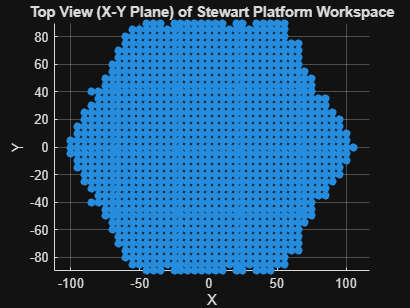


figure;
% Top view (X-Y plane)
scatter(X(workspace == 1), Y(workspace == 1), 'filled');
xlabel('X');
ylabel('Y');
title('Top View (X-Y Plane) of Stewart Platform Workspace');
grid on;
axis equal;

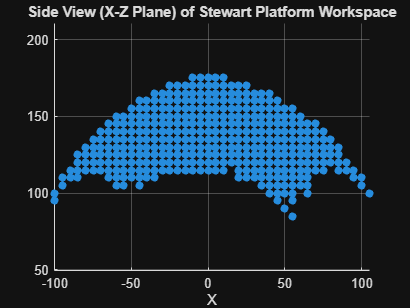


figure;
% Side view (X-Z plane)
scatter(X(workspace == 1), Z(workspace == 1), 'filled');
xlabel('X');
zlabel('Z');
title('Side View (X-Z Plane) of Stewart Platform Workspace');
grid on;
axis equal;

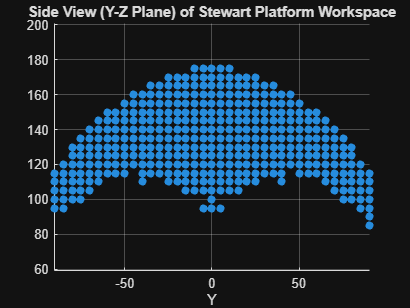


figure;
% Side view (Y-Z plane)
scatter(Y(workspace == 1), Z(workspace == 1), 'filled');
xlabel('Y');
zlabel('Z');
title('Side View (Y-Z Plane) of Stewart Platform Workspace');
grid on;
axis equal;

clc;
clear all;
% home position
beta = 0;
upperLegLength = 119.0; % Length of the upper legs (platform to servo joint)
lowerLegLength = 21.1; % Length of the lower legs (servo joint to base)
phi = deg2rad([22.41, 37.59, 142.41, 157.59, 262.41, 277.59]);
% vector of where the end of limb goes with respect to platform
b = 75.66;
platformPoints = b * [cos(phi); sin(phi); zeros(1, 6)];
d = 99.10;
theta = deg2rad([13.32, 46.68, 133.32, 166.68, 253.32, 286.68]);
% theta = deg2rad([9.33, 50.67, 129.33, 170.97, 249.33, 290.67]);
% vector of where servo rotation happens
% Check to see how off the z axis is 
basePoints = d * [cos(theta); sin(theta); zeros(1, 6)];
p = [0, 0, 100].';
q = p + eye(3)*platformPoints(:,6);
legVec = p + eye(3)*platformPoints(:,6) - basePoints(:,6);
legLength = norm(legVec);

% L = l^2 - (s^2 - a^2)
L = legLength - (upperLegLength - lowerLegLength);
% M = 2 * a (z_p - z_b)
M = 2 * lowerLegLength * (q(3, 1) - basePoints(3, 1));
% N = 2 * a * [cos(beta)*(x_p-x_b) + sin(beta)*(y_p - y_b)]
N = 2 * lowerLegLength * (cos(beta)*(q(1, 1) - basePoints(1, 1)) + sin(beta) * (q(2, 1) - basePoints(2, 1)) );
% alpha = sin^-1(L/(sqrt(M^2+N^2)) - tan^-1(N/M)
alpha = asind((L)/(sqrt(M^2+ N^2))) - atan2(N, M)

alpha = 0.7716

alpha = asind((L)/(sqrt(M^2+ N^2))) + atan2(N, M)

alpha = -0.6540



% h_0 = sqrt(upperLegLength + lowerLegLength + (q(1, 1) - basePoints(1, 1)) ^2+ (q(2, 1) - basePoints(2, 1))^2) - 